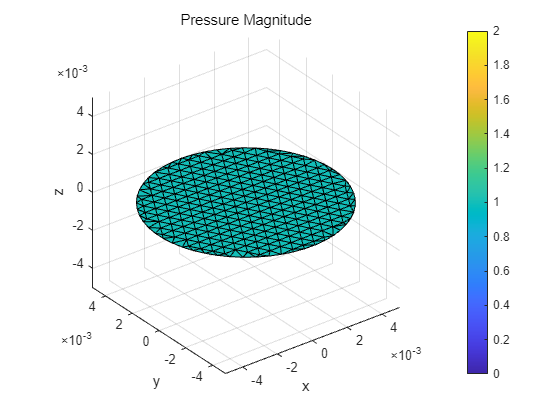

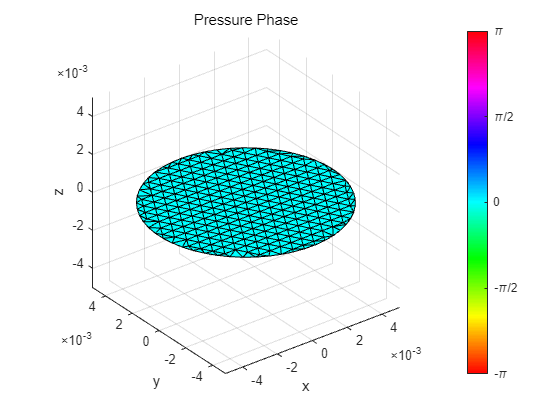

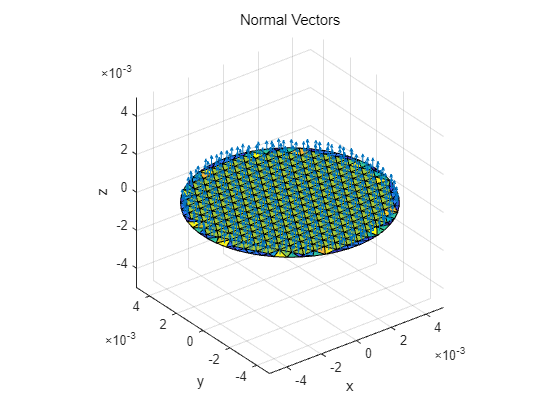

%% Transducer Design
transducer_info = [];

transducer_info.Frequency = 40000;
transducer_info.Pressure = 1;
transducer_info.Phase = 0;
transducer_info.Type = 'circle';
transducer_info.Radius = 5e-3;
transducer_info.medium = 'air';

transducer_object = PFC_Make3DTransducer(transducer_info);

PFC_DrawTransducer3D(transducer_object, '-');


%% Frequency Domain
input_source = [];

input_source.Type = 'frequency';
input_source.reading_list = 40000; % [Hz]



%% Simulation Space
reading_pos_x = -10e-3 : 0.1e-3 : 10e-3;          % Simulation Area
reading_pos_y = -10e-3 : 0.1e-3 : 10e-3;          % Simulation Area
reading_pos_z = 0e-3 : 0.1e-3 : 60e-3;          % Simulation Area



%% Run Frequency Domain Simulation

% xz plane
[Pressure_dxyz] = ...
PFC_CalculatePressureField(...
transducer_object, input_source,...                 % tx setting
reading_pos_x, 0, reading_pos_z);

Started at 2024-08-05 22:56:12
Finished at 2024-08-05 22:56:21
Progressed time : 00:00:08


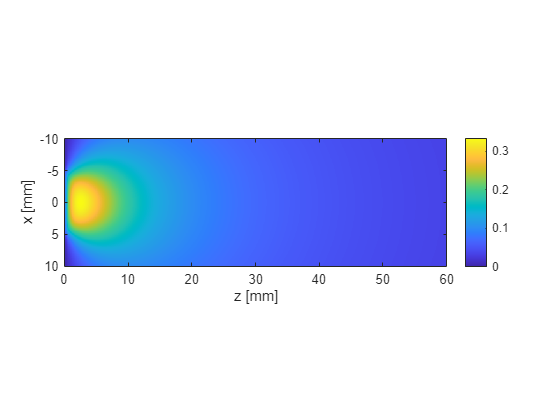


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

figure;imagesc(reading_pos_z.*1e3, reading_pos_x.*1e3, Pressure_dxyz_i);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top');
colorbar;
xlabel('z [mm]');
ylabel('x [mm]');


% xy plane
[Pressure_dxyz] = ...
PFC_CalculatePressureField(...
transducer_object, input_source,...                 % tx setting
reading_pos_x, reading_pos_y, 0.0166);

Started at 2024-08-05 22:56:22
Finished at 2024-08-05 22:56:25
Progressed time : 00:00:03


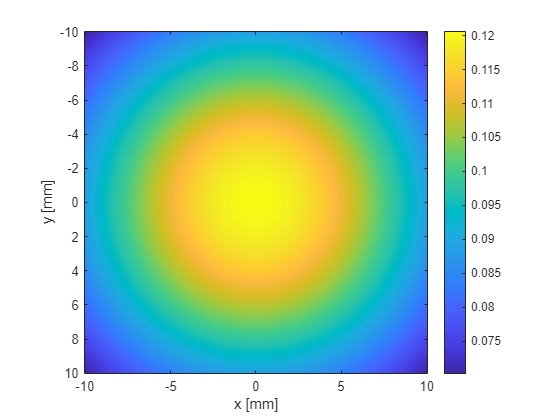


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

figure;imagesc(reading_pos_x.*1e3, reading_pos_y.*1e3, Pressure_dxyz_i);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top');
colorbar;
xlabel('x [mm]');
ylabel('y [mm]');